% Per a tots els vídeos
videoNames =dir("TinyTLP\");
nFrames = 100;
OverlappingRates = zeros([50, nFrames]);
for i=1:50
    name = videoNames(i).name;
    OverlappingRates(i,:) = ORatioSiftRansac(name,nFrames);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15



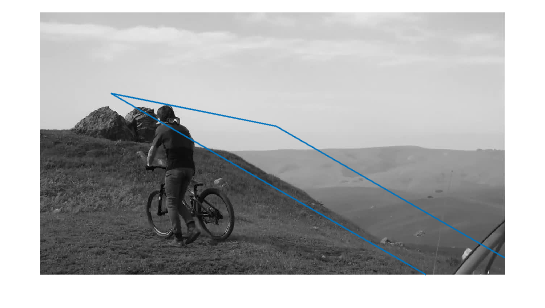

    16



% Per a una selecció de vídeos
videoNames = {'Alladin','PolarBear1'};
nFrames = 100;
OverlappingRates = zeros([size(videoNames,2), nFrames]);
for i=1:size(videoNames,2)
    name = videoNames{i};
    OverlappingRates(i,:) = ORatioSiftRansac(name,nFrames);
end

function [ORatio] = ORatioSiftRansac(nom_fitxer, nFrames)
    close all
    hold off

    % Obtenir nom de les imatges i del fitxer groundtruth_rect
    path1 = strcat('./TinyTLP/', nom_fitxer);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');
    
    % Obtenir Bounding Boxes Òptimes
    BB = importdata(path11);
    Idir = dir(path2);
    
    % Retall de l'objecte inicial
    filename = horzcat(Idir(1).folder,'/',Idir(1).name);
    I = imread(filename);
    B1 = BB(1,2:5);
    im_obje = rgb2gray(imcrop(I,B1));
    im_obj = im_obje(:,:,1);
    imshow(im_obj);
    
    % Vector de l'overlapping ratio de cada frame del vídeo
    ORatio = zeros(1,nFrames);

    for i = 1:nFrames
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I2 = imread(filename);

        im_esce = rgb2gray(I2);
        im_esc = im_esce(:,:,1);

        % SIFT
        kp_obj = detectSIFTFeatures(im_obj);
        kp_esc = detectSIFTFeatures(im_esc);
        [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
        [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

        % Emparallament
        pairs = matchFeatures(feat_obj, feat_esc);
        m_kp_obj = kp_obj(pairs(:,1));
        m_kp_esc = kp_esc(pairs(:,2));

        % Ransac
        if (m_kp_obj.Count >= 3) && (m_kp_esc.Count >= 3)
            % Càlcul transformació afi
            [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");
            
            % Càlcul Bounding Box
            Bi = BB(i,2:5);
            fo = Bi(4);
            co = Bi(3);
            box = [1,1; co,1; co,fo; 1,fo; 1,1];
            nbox = transformPointsForward(T,box);
            B2 = [nbox(1,1),nbox(1,2),Bi(3),Bi(4)];

            % Càlcul overlapping ratio
            ORatio(1,i) = bboxOverlapRatio(Bi,B2);

            % Mostrar imatges amb bounding box
            imshow(im_esc)
            hold on
            line(nbox(:,1),nbox(:,2));
            drawnow
        end
    end
end